clear
% d1=load("E:\MTP2\lulc\reclassified\LC_2015_re.mat");
% data=d1.LC_re;
d1=load("E:\MTP2\lulc\LC_2015_masked.mat");
data=d1.LC;

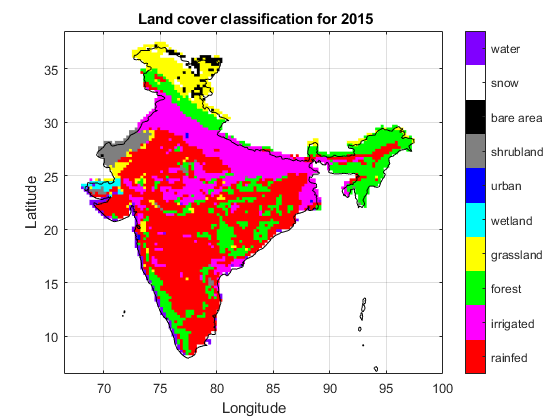

map = [1 0 0
    1 0 1
    0 1 0
    1 1 0
    0 1 1
    0 0 1
    0.5 0.5 0.5
    0 0 0
    1 1 1
    0.5 0 1];
figure;
% lat=(data(2:11611,1,1));
% lon=data(1,2:12151,1)';
% crop1=(data(2:11611,2:12151,1));
lat=(data(2:130,1,1));
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
%imshow(crop1);
%crop1=imageData;
%cropf_slope=fliplr(flipud(crop1));
%J(2:130,2:136,1)=fliplr(flipud(crop1));
%slp=pcolor(lon,lat,flipud(cropf_slope)); 
slp=pcolor(lon,lat,crop1);
slp.EdgeColor='none';
set(gca,'YDir','normal')
%slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
% colormap(flipud(jet)) % Setting a color scheme
% hcb1=colorbar; % Showing the scheme on a scale
cb1 = colorbar('Ticks',[100,200,300,400,500,600,700,800,900,1000],...
         'TickLabels',{'rainfed','irrigated','forest','grassland','wetland','urban','shrubland','bare area','snow','water'});
cb1=colormap((map));
caxis([50 1050])
ax1=gca;
title(' Land cover classification for 2015'); % Putting title to the figure
% %caxis([-0.3 0.5])
% %title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile

% x = [5 8];
% y = [3 6];
% C = [0 2 4 6; 8 10 12 14; 16 18 20 22];
% set(gca,'YDir','reverse')
% imagesc(x,y,C)
